# Tracking a ballistic object on reentry

Reference: Beyond the Kalman Filter, B. Ristic, chapter 5

this simulation deals with tracking an object ( asteroid, satellite, missile... ) as it enters the Earth's atmosphere. Two simplifications: the radar's measurement model is not actually linear, and the asteroid is not likely to fall following a vertical trajectory, rather an angled one...

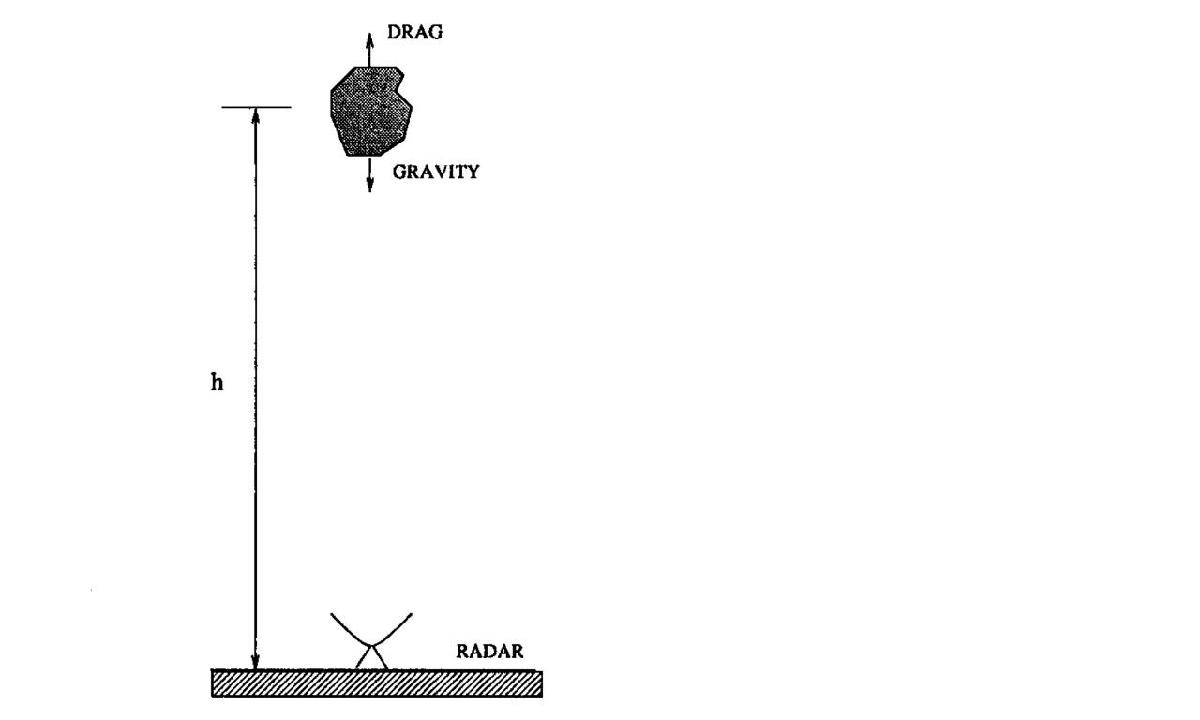

## Simulation parameters


N = 300;
x = zeros(3,N+1);

x(:,1) = [61e3 ; 3048; 19161];
tau = 0.1;
q1 = 0;
q2 = 0;
Q = [q1*tau*tau*tau/3, q1*tau*tau*0.5, 0;
     q1*tau*tau*0.5, q1*tau, 0;
     0 0 q2*tau];

y = zeros(1,N);
H = [1, 0, 0];
R = 200*200; % Sensor noise variance
T = tau; % Capital T is the sensor frequency



## Simulation


for i = 1 : N
    x(:,i+1) = f(x(:,i),tau) + mvnrnd([0 0 0]', Q)';
    y(:,i) = H*x(:,i) + sqrt(R)*randn();
end
x

x = 1.0e+04 *

    6.1000    6.0695    6.0390    6.0085    5.9780    5.9475    5.9170    5.8864    5.8559    5.8253    5.7948    5.7642    5.7336    5.7030    5.6724    5.6418    5.6112    5.5806    5.5500    5.5193    5.4887    5.4580    5.4273    5.3966    5.3660    5.3353    5.3046    5.2739    5.2431    5.2124    5.1817    5.1509    5.1202    5.0894    5.0586    5.0279    4.9971    4.9663    4.9355    4.9047    4.8739    4.8431    4.8122    4.7814    4.7506    4.7197    4.6889    4.6580    4.6271    4.5963
    0.3048    0.3049    0.3050    0.3051    0.3052    0.3053    0.3054    0.3054    0.3055    0.3056    0.3057    0.3058    0.3059    0.3060    0.3061    0.3062    0.3063    0.3063    0.3064    0.3065    0.3066    0.3067    0.3068    0.3069    0.3070    0.3070    0.3071    0.3072    0.3073    0.3074    0.3074    0.3075    0.3076    0.3077    0.3078    0.3078    0.3079    0.3080    0.3081    0.3081    0.3082    0.3083    0.3083    0.3084    0.3085    0.3085    0.3086    0.3086    

y

y = 1.0e+04 *

    6.1095    6.0614    6.0578    5.9872    5.9976    5.9254    5.9220    5.8358    5.8608    5.8140    5.7714    5.7881    5.7400    5.6817    5.6633    5.6468    5.6114    5.5786    5.4978    5.5091    5.4807    5.4325    5.4130    5.3951    5.4176    5.3093    5.3044    5.2305    5.2448    5.1909    5.1915    5.1240    5.1300    5.0833    5.0557    5.0461    4.9879    4.9676    4.9455    4.9067    4.8747    4.8229    4.8033    4.7766    4.7526    4.7551    4.6824    4.6659    4.6370    4.6232


## Plot noiseless trajectory + noisy sensor measurements

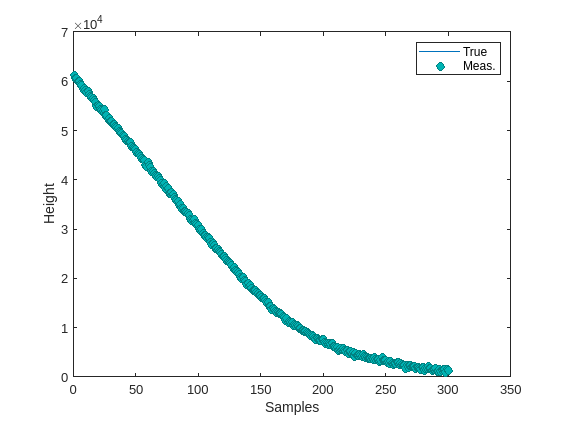


figure
plot(x(1,:))
xlabel("Samples")
ylabel("Height")
hold on;
scatter([1:1:N], y(1,:),'MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',0.2)
legend("True","Meas.")

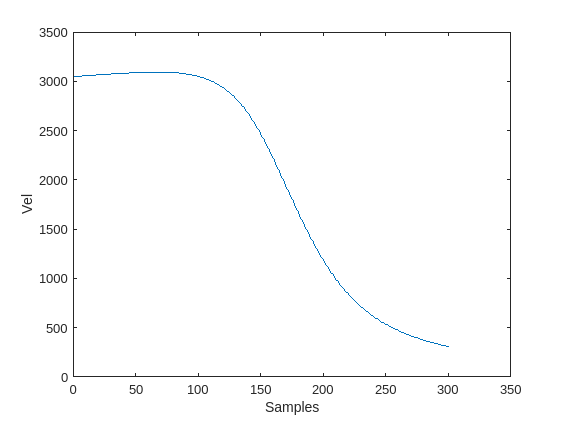


figure
plot(x(2,:))
xlabel("Samples")
ylabel("Vel")

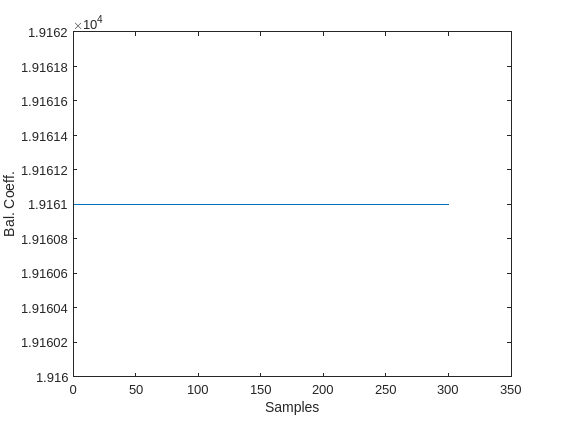


figure
plot(x(3,:))
xlabel("Samples")
ylabel("Bal. Coeff.")

## Initial variance of object


sigma_beta = 7184; % Variance of ballistic coeff.
P_0 = [R , R/tau , 0;
            R/tau , 2*R/(tau*tau) , 0;
            0 , 0 , sigma_beta*sigma_beta];


## CRLB (noiseless)

here we compute the Cramer Rao Lower Bound for the given samples

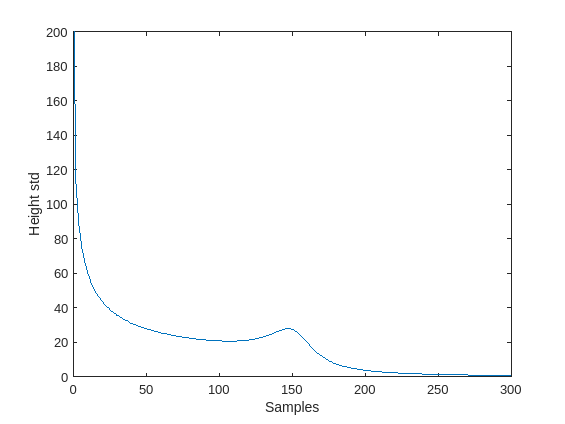

J = zeros(3,3,N);
J(:,:,1) = inv(P_0); % For gaussian densities the information matrix is the inverse of the cov. matrix
CRLB = zeros(3,3,N);
CRLB(:,:,1) = P_0;
cholCRLB = zeros(3,3,N);
cholCRLB(:,:,1) = chol(CRLB(:,:,1));

invR = inv(R);
g = 9.80665;
eta = 1.49e-4;

for i = 2 : N
    f21 = eta*g*p(x(1,i))*x(2,i)*x(2,i)/(2*x(3,i));
    f22 = g*p(x(1,i))*x(2,i)/x(3,i);
    f23 = g*p(x(1,i))*x(2,i)/(2*x(3,i)*x(3,i));
    Ftilde = [1, -tau, 0;
              f21*tau, 1-f22*tau, f23*tau;
              0, 0, 1];
    invFtilde = inv(Ftilde);
    J(:,:,i) = (H')*invR*H + (invFtilde')*J(:,:,i-1)*invFtilde;
    diagJ = diag(diag(J(:,:,i)));
    CRLB(:,:,i) = inv(diagJ);
    cholCRLB(:,:,i) = chol(CRLB(:,:,i));
end

% Now we plot the result


%plot. squeeze reshapes the vectors into columns rather than timeseries so i use transpose

figure
plot( squeeze(cholCRLB(1,1,:))' )
xlabel("Samples")
ylabel("Height std")

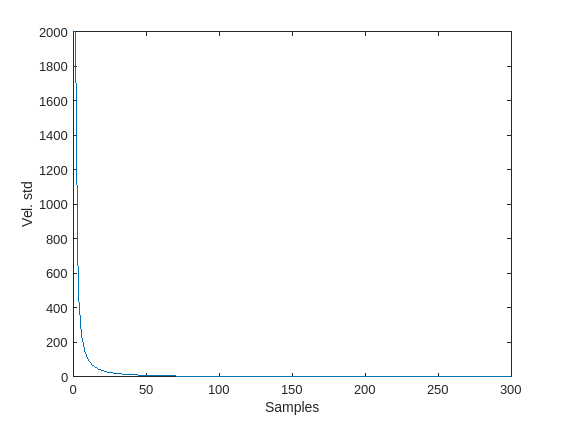


figure
plot( squeeze(cholCRLB(2,2,:))' )
xlabel("Samples")
ylabel("Vel. std")

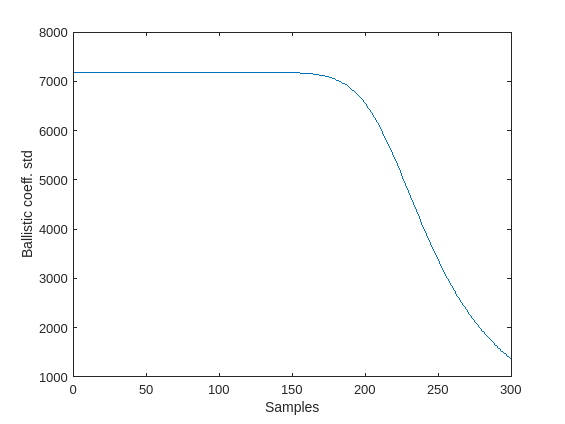


figure
plot( squeeze(cholCRLB(3,3,:))' )
xlabel("Samples")
ylabel("Ballistic coeff. std")

Remember that the CRLB constitutes a true lower bound only up to second order statistics. Neverthless, it's still a useful benchmark

#### CRLB (Noisy)

here we vary the process noise.

This is the recursion in the presence of process noise

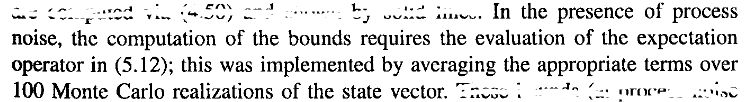

We wish to create two timeseries:

1)Matrix Timeseries of Ftilde over time. 

2)Matrix Timeseries of the product (Ftilde')QFtilde over time

q1 = 5;
q2 = 5; % Change the amount of noise
Q = [q1*tau*tau*tau/3, q1*tau*tau*0.5, 0;
     q1*tau*tau*0.5, q1*tau, 0;
     0 0 q2*tau];

x = zeros(3,N+1);
x(:,1) = [61e3 ; 3048; 19161];

M = 100; % This is the number of monte carlo runs
FtildeS = zeros(3,3,N,M);
FtinvQFS = zeros(3,3,N,M);


invQ = inv(Q);

for j = 1 : M
    x(:,1) = [61e3 ; 3048; 19161]; % Reset the initial condition
    for i = 1 : N
            f21 = eta*g*p(x(1,i))*x(2,i)*x(2,i)/(2*x(3,i));
            f22 = g*p(x(1,i))*x(2,i)/x(3,i);
            f23 = g*p(x(1,i))*x(2,i)/(2*x(3,i)*x(3,i));
            Ftilde = [ 1, -tau, 0;
                       f21*tau, 1-f22*tau, f23*tau;
                       0, 0, 1]; 
            FtildeS(:,:,i,j) = Ftilde;
            FtinvQFS(:,:,i,j) = (Ftilde')*invQ*Ftilde;
            x(:,i+1) = f(x(:,i),tau) + mvnrnd([0 0 0]', Q)'; % Compute nxt variable
    end
end


% Now we have to compute the noisy CRLB. Take the same code we used before,
% but now we have precomputed the gradient

J = zeros(3,3,N);
J(:,:,1) = inv(P_0); % For gaussian densities the information matrix is the inverse of the cov. matrix

noiselessCholCRLB = cholCRLB; % Save noiselss result

CRLB = zeros(3,3,N);
CRLB(:,:,1) = P_0;
cholCRLB = zeros(3,3,N);
cholCRLB(:,:,1) = chol(CRLB(:,:,1));

% ev before the variable name stands for "expected value". We evaluate it
% in the following way:
% 1) First, consider the kth column of the 3rd dimension, that is where we have stored
% the evaluations related to the kth time for all the runs
% 2) Then, sum columnwise on the 4th dimension, that is the sample space,
% and average by M



    

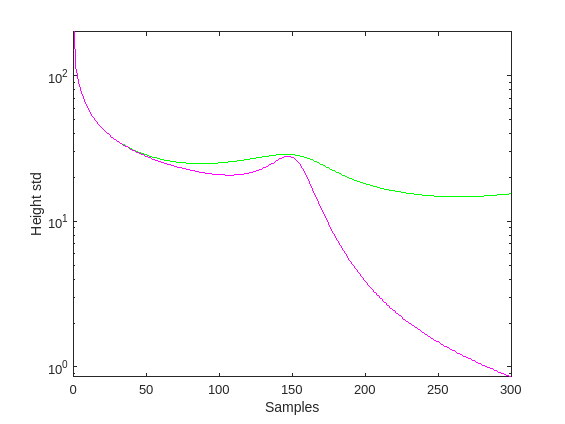

for k = 2 : N 
    %
      evFtilde = zeros(3,3);
      evFtinvQFS =  zeros(3,3); % Reset the sum
            for j = 1 : M
               evFtilde = evFtilde + FtildeS(:,:,k,j);
               evFtinvQFS =  evFtinvQFS + FtinvQFS(:,:,k,j) ;
            end
            evFtilde = evFtilde/M;
            evFtinvQFS = evFtinvQFS/M;
   %
    J(:,:,k) = invQ + (H')*invR*H - invQ*evFtilde*inv(evFtinvQFS + J(:,:,k-1) )*(evFtilde')*invQ; % This looks 
    diagJ = diag(diag(J(:,:,k)));
    CRLB(:,:,k) = inv(diagJ);
    cholCRLB(:,:,k) = chol(CRLB(:,:,k));
end


figure
semilogy( squeeze(cholCRLB(1,1,:))'  , "green")
xlabel("Samples")
ylabel("Height std")
hold on
semilogy( squeeze(noiselessCholCRLB(1,1,:))' , "magenta" )

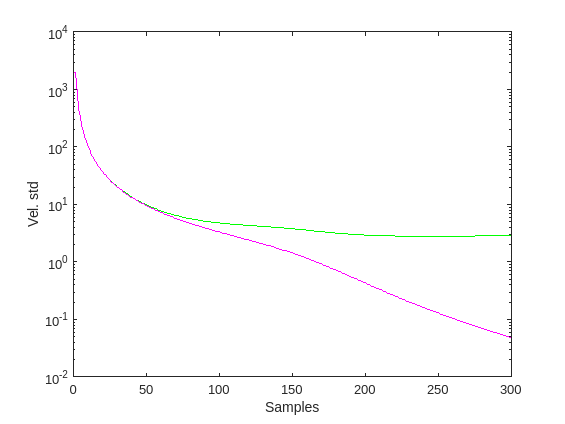



figure
semilogy( squeeze(cholCRLB(2,2,:))',"green")
xlabel("Samples")
ylabel("Vel. std")
hold on
semilogy( squeeze(noiselessCholCRLB(2,2,:))' , "magenta" )

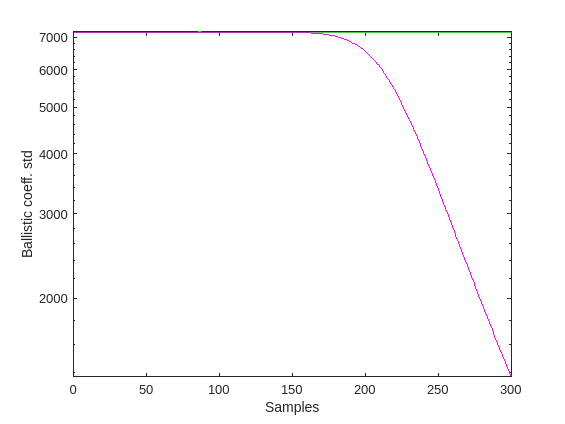

%%%%%%%%%% =============================================
figure % This doesn't plot in log scale for some  reason ?????????
semilogy( squeeze(cholCRLB(3,3,:))', "green"  )
xlabel("Samples")
ylabel("Ballistic coeff. std")
hold on
semilogy( squeeze(noiselessCholCRLB(3,3,:))' ,  "magenta" )

%%%%%%%%%% =============================================


# Estimation algorithms

Regenerate a (noisy) target state trajectory once more. Then we declare the covariance for whichever state estimate we might apply afterwards

x = zeros(3,N+1);
x(:,1) = [61e3 ; 3048; 19161];
q1 = 5;
q2 = 5; % Change the amount of noise
Q = [q1*tau*tau*tau/3, q1*tau*tau*0.5, 0;
     q1*tau*tau*0.5, q1*tau, 0;
     0 0 q2*tau];

for i = 1 : N
    x(:,i+1) = f(x(:,i),tau) + mvnrnd([0 0 0]', Q)';
    y(:,i) = H*x(:,i) + sqrt(R)*randn();
end
x

x = 1.0e+04 *

    6.1000    6.0695    6.0390    6.0085    5.9780    5.9475    5.9169    5.8863    5.8558    5.8252    5.7946    5.7640    5.7333    5.7027    5.6720    5.6414    5.6107    5.5800    5.5493    5.5186    5.4879    5.4572    5.4265    5.3957    5.3650    5.3342    5.3034    5.2727    5.2419    5.2111    5.1803    5.1495    5.1187    5.0879    5.0571    5.0263    4.9954    4.9646    4.9338    4.9030    4.8721    4.8413    4.8104    4.7795    4.7487    4.7178    4.6869    4.6560    4.6251    4.5942
    0.3048    0.3050    0.3050    0.3052    0.3054    0.3056    0.3056    0.3057    0.3059    0.3061    0.3063    0.3064    0.3064    0.3067    0.3067    0.3067    0.3068    0.3069    0.3070    0.3070    0.3072    0.3073    0.3074    0.3075    0.3076    0.3077    0.3077    0.3078    0.3079    0.3079    0.3079    0.3080    0.3081    0.3081    0.3082    0.3082    0.3082    0.3083    0.3083    0.3084    0.3085    0.3085    0.3086    0.3086    0.3087    0.3089    0.3090    0.3091    

y

y = 1.0e+04 *

    6.1206    6.0712    6.0518    6.0265    6.0158    5.9539    5.9178    5.9002    5.8614    5.8459    5.7951    5.7584    5.7030    5.7465    5.6665    5.6527    5.5819    5.5752    5.5486    5.5313    5.4889    5.4717    5.4375    5.4177    5.3701    5.3198    5.2838    5.2649    5.2267    5.2178    5.1785    5.1493    5.1333    5.0803    5.0556    5.0029    5.0046    4.9735    4.9313    4.9230    4.8654    4.8096    4.8136    4.7705    4.7308    4.6897    4.6844    4.6780    4.6354    4.5867


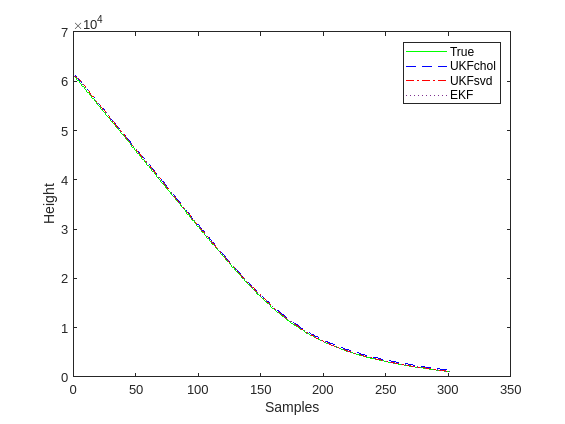


P_ukf_chol = zeros(3,3,N+1);
P_ukf_chol(:,:,1) = P_0;
x_hat_ukf_chol = zeros(3,N+1);
x_hat_ukf_chol(:,1) = x(:,1);
kappa_chol = 1.65;


P_ukf_svd = zeros(3,3,N+1);
P_ukf_svd(:,:,1) = P_0;
x_hat_ukf_svd = zeros(3,N+1);
x_hat_ukf_svd(:,1) = x(:,1);
kappa_svd = 1;

x_hat_ekf = zeros(3,N+1);
x_hat_ekf(:,1) = x(:,1);
P_ekf = zeros(3,3,N+1);
P_ekf(:,:,1) = P_0;

for i = 1 : N
   [ x_hat_ukf_chol(:,i+1) , P_ukf_chol(:,:,i+1) ] = myukfchol( x_hat_ukf_chol(:,i) , P_ukf_chol(:,:,i) , tau , Q, y(:,i) , R, kappa_chol); % the input is the sampling time
   [ x_hat_ukf_svd(:,i+1) , P_ukf_svd(:,:,i+1) ] = myukfsvd( x_hat_ukf_svd(:,i) , P_ukf_svd(:,:,i) , tau , Q, y(:,i) , R, kappa_svd); % the input is the sampling time 
   [ x_hat_ekf(:,i+1) , P_ekf(:,:,i+1) ] = myekf( x_hat_ekf(:,i) , P_ekf(:,:,i) , tau , Q, y(:,i) , R);
end

% Plot the results
figure
plot(x(1,:), "Color","g")
xlabel("Samples")
ylabel("Height")
hold on;
plot(x_hat_ukf_chol(1,:),"LineStyle","--","Color","b")
plot(x_hat_ukf_svd(1,:),"LineStyle","-.","Color","r")
plot(x_hat_ekf(1,:),"LineStyle",":","Color",[0.4940, 0.1840, 0.5560],"LineWidth",1)
legend("True","UKFchol","UKFsvd","EKF")

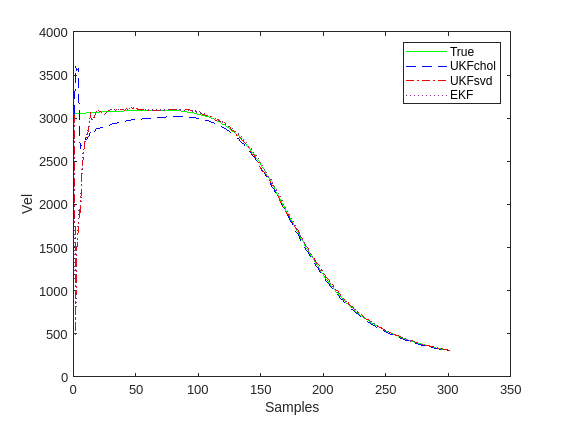


figure
plot(x(2,:), "Color","g")
xlabel("Samples")
ylabel("Vel")
hold on;
plot(x_hat_ukf_chol(2,:),"LineStyle","--","Color","b")
plot(x_hat_ukf_svd(2,:),"LineStyle","-.","Color","r")
plot(x_hat_ekf(2,:),"LineStyle",":","Color",[0.4940, 0.1840, 0.5560],"LineWidth",1)
legend("True","UKFchol","UKFsvd","EKF")

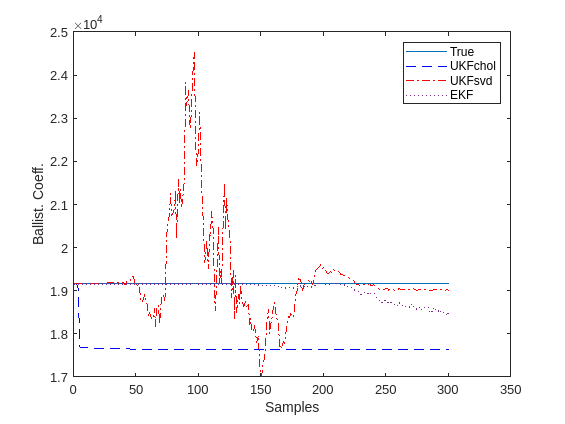



figure
plot(x(3,:))
xlabel("Samples")
ylabel("Ballist. Coeff.")
hold on;
plot(x_hat_ukf_chol(3,:),"LineStyle","--","Color","b")
plot(x_hat_ukf_svd(3,:),"LineStyle","-.","Color","r")
plot(x_hat_ekf(3,:),"LineStyle",":","Color",[0.4940, 0.1840, 0.5560],"LineWidth",1)
legend("True","UKFchol","UKFsvd","EKF")

## Filter takeaways

The UKF using cholesky decomposition presents significant bias in the ball. coeff estimation. This is very sensitive to the choice of the scaling parameter kappa_chol

The UKF using svd performs slightly better in the long run

Overall the EKF is the best performer. The ballistic coeff. estimate oscillates after N > 300 but this is not a problem, as the tracked asteroid has already touched ground.

## Estimation of Information Matrix of tested filters

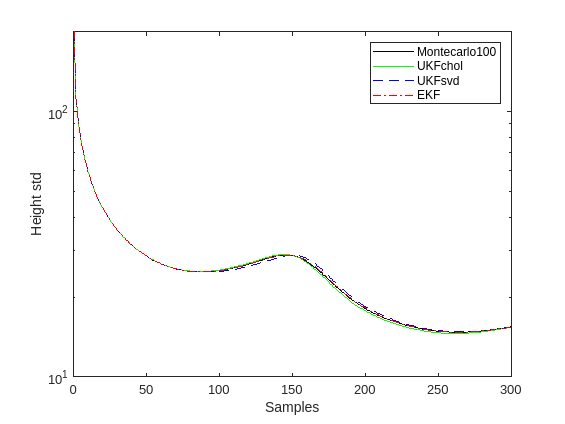

% UKF_chol

for j = 1 : M
    for i = 1 : N
            f21 = eta*g*p(x_hat_ukf_chol(1,i))*x_hat_ukf_chol(2,i)*x_hat_ukf_chol(2,i)/(2*x_hat_ukf_chol(3,i));
            f22 = g*p(x_hat_ukf_chol(1,i))*x_hat_ukf_chol(2,i)/x_hat_ukf_chol(3,i);
            f23 = g*p(x_hat_ukf_chol(1,i))*x_hat_ukf_chol(2,i)/(2*x_hat_ukf_chol(3,i)*x_hat_ukf_chol(3,i));
            Ftilde = [ 1, -tau, 0;
                       f21*tau, 1-f22*tau, f23*tau;
                       0, 0, 1]; 
            FtildeS(:,:,i,j) = Ftilde;
            FtinvQFS(:,:,i,j) = (Ftilde')*invQ*Ftilde;
    end
end

J_ukf_chol = zeros(3,3,N);
J_ukf_chol(:,:,1) = inv(P_0); % For gaussian densities the information matrix is the inverse of the cov. matrix
CRLB_ukf_chol = zeros(3,3,N);
CRLB_ukf_chol(:,:,1) = P_0;
cholCRLB_ukf_chol = zeros(3,3,N);
cholCRLB_ukf_chol(:,:,1) = chol(CRLB_ukf_chol(:,:,1));

for k = 2 : N 
    %
      evFtilde = zeros(3,3);
      evFtinvQFS =  zeros(3,3); % Reset the sum
            for j = 1 : M
               evFtilde = evFtilde + FtildeS(:,:,k,j);
               evFtinvQFS =  evFtinvQFS + FtinvQFS(:,:,k,j) ;
            end
            evFtilde = evFtilde/M;
            evFtinvQFS = evFtinvQFS/M;
   %
    J_ukf_chol(:,:,k) = invQ + (H')*invR*H - invQ*evFtilde*inv(evFtinvQFS + J_ukf_chol(:,:,k-1) )*(evFtilde')*invQ; % This looks 
    diagJ = diag(diag(J_ukf_chol(:,:,k)));
    CRLB_ukf_chol(:,:,k) = inv(diagJ);
    cholCRLB_ukf_chol(:,:,k) = chol(CRLB_ukf_chol(:,:,k));
end


% ukf_svd

for j = 1 : M
    for i = 1 : N
            f21 = eta*g*p(x_hat_ukf_svd(1,i))*x_hat_ukf_svd(2,i)*x_hat_ukf_svd(2,i)/(2*x_hat_ukf_svd(3,i));
            f22 = g*p(x_hat_ukf_svd(1,i))*x_hat_ukf_svd(2,i)/x_hat_ukf_svd(3,i);
            f23 = g*p(x_hat_ukf_svd(1,i))*x_hat_ukf_svd(2,i)/(2*x_hat_ukf_svd(3,i)*x_hat_ukf_svd(3,i));
            Ftilde = [ 1, -tau, 0;
                       f21*tau, 1-f22*tau, f23*tau;
                       0, 0, 1]; 
            FtildeS(:,:,i,j) = Ftilde;
            FtinvQFS(:,:,i,j) = (Ftilde')*invQ*Ftilde;
    end
end

J_ukf_svd = zeros(3,3,N);
J_ukf_svd(:,:,1) = inv(P_0); % For gaussian densities the information matrix is the inverse of the cov. matrix
CRLB_ukf_svd = zeros(3,3,N);
CRLB_ukf_svd(:,:,1) = P_0;
cholCRLB_ukf_svd = zeros(3,3,N);
cholCRLB_ukf_svd(:,:,1) = chol(CRLB_ukf_svd(:,:,1));

for k = 2 : N 
    %
      evFtilde = zeros(3,3);
      evFtinvQFS =  zeros(3,3); % Reset the sum
            for j = 1 : M
               evFtilde = evFtilde + FtildeS(:,:,k,j);
               evFtinvQFS =  evFtinvQFS + FtinvQFS(:,:,k,j) ;
            end
            evFtilde = evFtilde/M;
            evFtinvQFS = evFtinvQFS/M;
   %
    J_ukf_svd(:,:,k) = invQ + (H')*invR*H - invQ*evFtilde*inv(evFtinvQFS + J_ukf_svd(:,:,k-1) )*(evFtilde')*invQ; % This looks 
    diagJ = diag(diag(J_ukf_svd(:,:,k)));
    CRLB_ukf_svd(:,:,k) = inv(diagJ);
    cholCRLB_ukf_svd(:,:,k) = chol(CRLB_ukf_svd(:,:,k));
end



% ekf

for j = 1 : M
    for i = 1 : N
            f21 = eta*g*p(x_hat_ekf(1,i))*x_hat_ekf(2,i)*x_hat_ekf(2,i)/(2*x_hat_ekf(3,i));
            f22 = g*p(x_hat_ekf(1,i))*x_hat_ekf(2,i)/x_hat_ekf(3,i);
            f23 = g*p(x_hat_ekf(1,i))*x_hat_ekf(2,i)/(2*x_hat_ekf(3,i)*x_hat_ekf(3,i));
            Ftilde = [ 1, -tau, 0;
                       f21*tau, 1-f22*tau, f23*tau;
                       0, 0, 1]; 
            FtildeS(:,:,i,j) = Ftilde;
            FtinvQFS(:,:,i,j) = (Ftilde')*invQ*Ftilde;
    end
end

J_ekf = zeros(3,3,N);
J_ekf(:,:,1) = inv(P_0); % For gaussian densities the information matrix is the inverse of the cov. matrix
CRLB_ekf = zeros(3,3,N);
CRLB_ekf(:,:,1) = P_0;
cholCRLB_ekf = zeros(3,3,N);
cholCRLB_ekf(:,:,1) = chol(CRLB_ekf(:,:,1));

for k = 2 : N 
    %
      evFtilde = zeros(3,3);
      evFtinvQFS =  zeros(3,3); % Reset the sum
            for j = 1 : M
               evFtilde = evFtilde + FtildeS(:,:,k,j);
               evFtinvQFS =  evFtinvQFS + FtinvQFS(:,:,k,j) ;
            end
            evFtilde = evFtilde/M;
            evFtinvQFS = evFtinvQFS/M;
   %
    J_ekf(:,:,k) = invQ + (H')*invR*H - invQ*evFtilde*inv(evFtinvQFS + J_ekf(:,:,k-1) )*(evFtilde')*invQ; % This looks 
    diagJ = diag(diag(J_ekf(:,:,k)));
    CRLB_ekf(:,:,k) = inv(diagJ);
    cholCRLB_ekf(:,:,k) = chol(CRLB_ekf(:,:,k));
end

% Plot the results
figure
semilogy( squeeze(cholCRLB(1,1,:))'  , "black")
xlabel("Samples")
ylabel("Height std")
hold on;
semilogy(squeeze(cholCRLB_ukf_chol(1,1,:)), "Color","g")
semilogy(squeeze(cholCRLB_ukf_svd(1,1,:)),"LineStyle","--","Color","b")
semilogy(squeeze(cholCRLB_ekf(1,1,:)),"LineStyle","-.","Color","r")
legend("Montecarlo"+ M,"UKFchol","UKFsvd","EKF")

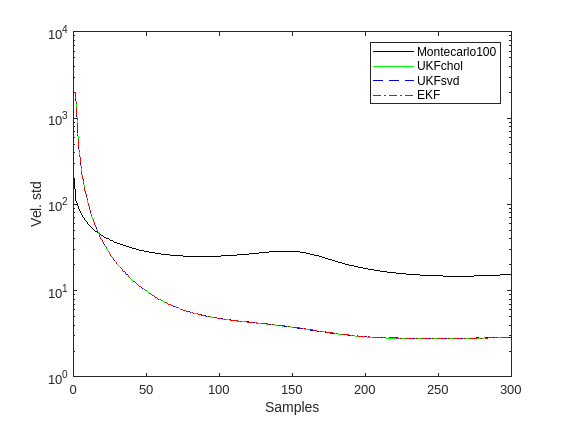


figure
semilogy( squeeze(cholCRLB(1,1,:))'  , "black")
xlabel("Samples")
ylabel("Vel. std")
hold on;
semilogy(squeeze(cholCRLB_ukf_chol(2,2,:)), "Color","g")
semilogy(squeeze(cholCRLB_ukf_svd(2,2,:)),"LineStyle","--","Color","b")
semilogy(squeeze(cholCRLB_ekf(2,2,:)),"LineStyle","-.","Color","r")
legend("Montecarlo"+ M,"UKFchol","UKFsvd","EKF")

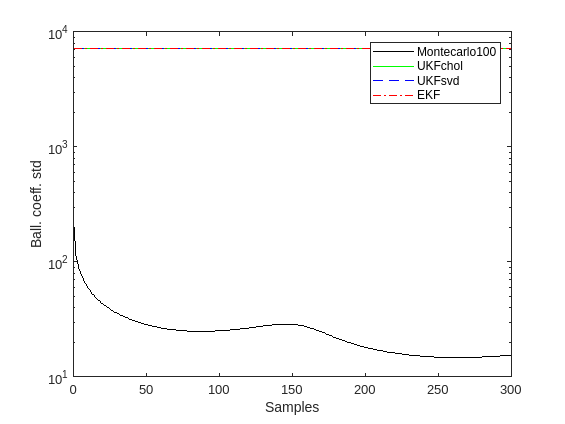


figure
semilogy( squeeze(cholCRLB(1,1,:))'  , "black")
xlabel("Samples")
ylabel("Ball. coeff. std")
hold on;
semilogy(squeeze(cholCRLB_ukf_chol(3,3,:)), "Color","g")
semilogy(squeeze(cholCRLB_ukf_svd(3,3,:)),"LineStyle","--","Color","b")
semilogy(squeeze(cholCRLB_ekf(3,3,:)),"LineStyle","-.","Color","r")
legend("Montecarlo"+ M,"UKFchol","UKFsvd","EKF")

#### **Some takeaways**

The (noisy) CRLB is reached by every filter for the height parameter

The Filters outperform the CRLB for the velocity estimation. This is possible if the filters are biased estimators for the parameter. We can verify if it is the case by computing residuals and seeing if we have a zero mean process. 

res_ukf_chol = x(2,:) - x_hat_ukf_chol(2,:) ;
res_ukf_svd= x(2,:) - x_hat_ukf_svd(2,:) ;
res_ekf = x(2,:) - x_hat_ekf(2,:) ;

mean_v_ukf_chol = mean(v_res_ukf_chol,2)

mean_v_ukf_chol = 203.8925

mean_v_ukf_svd = mean(v_res_ukf_svd,2)

mean_v_ukf_svd = 24.4600

mean_v_ekf = mean(v_res_ekf,2)

mean_v_ekf = 23.5280

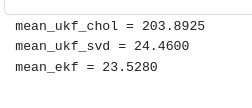

This mean is computed for 300 samples. The result is the same if one increases N atop of the simulation to 1000 and beyond

The ballistic coefficent std stays the same for every filter. This is either an unforeseen error in the code, or in the computation of the information matrix... 

Overall the EKF is once again the winner, having an edge on the SVD UKF by introducing slightly less bias. It should be noted that most of the bias is accumulated in the initial part of the run, as shown here

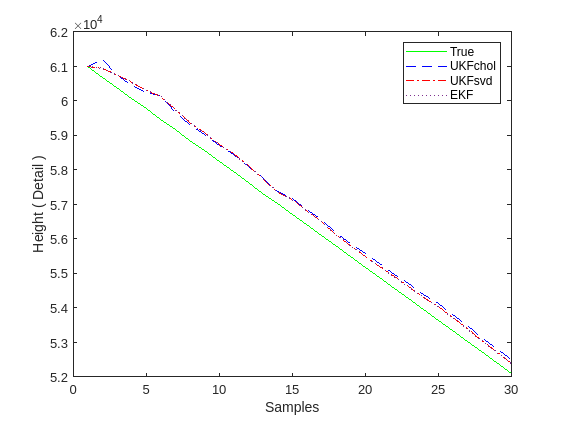


% Plot the results
figure
plot(x(1,[1:(N/10)]), "Color","g")
xlabel("Samples")
ylabel("Height ( Detail )")
hold on;
plot(x_hat_ukf_chol(1,[1:(N/10)]),"LineStyle","--","Color","b")
plot(x_hat_ukf_svd(1,[1:(N/10)]),"LineStyle","-.","Color","r")
plot(x_hat_ekf(1,[1:(N/10)]),"LineStyle",":","Color",[0.4940, 0.1840, 0.5560],"LineWidth",1)
legend("True","UKFchol","UKFsvd","EKF")

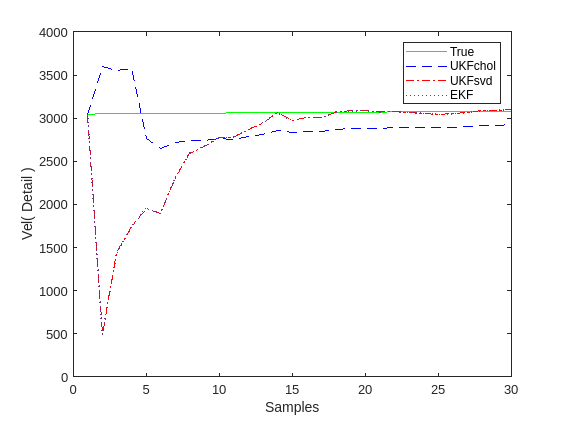


figure
plot(x(2,[1:(N/10)]), "Color","g")
xlabel("Samples")
ylabel("Vel( Detail )")
hold on;
plot(x_hat_ukf_chol(2,[1:(N/10)]),"LineStyle","--","Color","b")
plot(x_hat_ukf_svd(2,[1:(N/10)]),"LineStyle","-.","Color","r")
plot(x_hat_ekf(2,[1:(N/10)]),"LineStyle",":","Color",[0.4940, 0.1840, 0.5560],"LineWidth",1)
legend("True","UKFchol","UKFsvd","EKF")

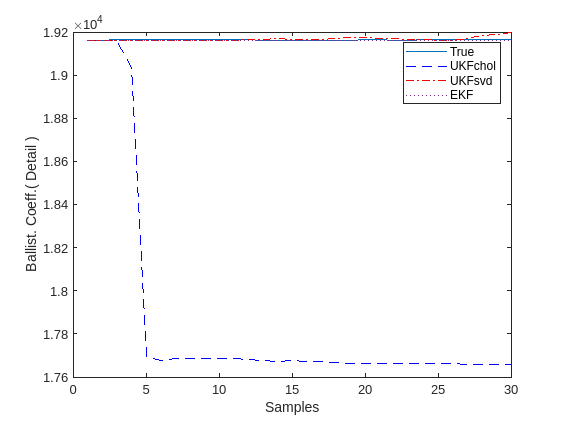



figure
plot(x(3,[1:(N/10)]))
xlabel("Samples")
ylabel("Ballist. Coeff.( Detail )")
hold on;
plot(x_hat_ukf_chol(3,[1:(N/10)]),"LineStyle","--","Color","b")
plot(x_hat_ukf_svd(3,[1:(N/10)]),"LineStyle","-.","Color","r")
plot(x_hat_ekf(3,[1:(N/10)]),"LineStyle",":","Color",[0.4940, 0.1840, 0.5560],"LineWidth",1)
legend("True","UKFchol","UKFsvd","EKF")

FUNCTIONS

function [p_out] = p(h_in)
gamma = 1.754;
eta = 1.49e-4;
p_out = gamma*exp(-eta*h_in);
end
    
function [x_nxt] = f(x,tau)
%Constants
g = 9.80665;

h = x(1);
v = x(2);
beta = x(3);

p_h = p(h);

h_dot = -v;
v_dot = -(p_h*g*v*v)/(2*beta) + g;
beta_dot = 0;

x_nxt =  x + tau*[h_dot ; v_dot; beta_dot];

end
